# Bag of visual words

This question challenges you to write some code for classifying images of different animals using a Bag of Visual Words (BoVW). Before you jump in and start coding, **you are strongly encouraged to take time to read through the following references**:

This first reading gives an overview of the theory behind the BoVW approach, and the key Matlab functions involved in applying it:

- [https://uk.mathworks.com/help/vision/ug/image-classification-with-bag-of-visual-words.html](https://uk.mathworks.com/help/vision/ug/image-classification-with-bag-of-visual-words.html)

This second reading shows all the steps involved in an application of the BoVW approach to an image classification problem:

- [https://uk.mathworks.com/help/vision/examples/image-category-classification-using-bag-of-features.html](https://uk.mathworks.com/help/vision/examples/image-category-classification-using-bag-of-features.html)

(Once you have completed the readings...) Marks are available for:

- Loading and splitting the images in the "Animals" directory; 60% for training, 40% for testing [4 marks]

- Building a BoVW from your training images [2 marks]

- Encoding *a single* testing image using the bag, and plotting the frequency of occurrence of each visual word in a graph with suitably labelled axes and title [5 marks]

- Training a classifier from the bag and evaluating its overall accuracy on *all of* your testing images [5 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

[Hint: on this particular pair of animals you should find a BoVW classifier gives excellent (perhaps even perfect) results]

% unzip our dataset if we haven't already...
% the resulting /Animals directory contains:
% 1. a subdirectory called /leopards containing images of leopards
% 2. a subdirectory called /llamas containing images of llamas

if ~isfolder('./Animals')
    unzip('Animals.zip');
end

% Add as many lines of code as you need below:

%load the image collection using an imageDatastore, used to manage the
%data. operates on file locations and does not load into memory 
imds = imageDatastore('./Animals/', 'IncludeSubfolders',true, 'LabelSource','foldernames');

%inspect the number of images per category and category labels 
tbl = countEachLabel(imds)

tbl = 2×2 table
     Label      Count
    ________    _____

    leopards     78  
    llama        78  


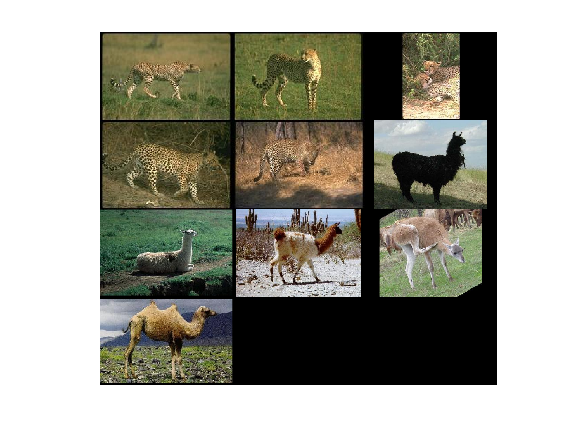


%display a few of the images to get a feel for the type of images being used
figure
montage(imds.Files(1:16:end))


%split images into training set (60% of images) and testing set (40% of images)
[trainingSet, testingSet] = splitEachLabel(imds, 0.6, 'randomize');

%call bagOfFeatures() function on the training set, it extracts SURF
%features from all images in all image categories and constructs the visual
%vocabulary by reducing the number of features through quantization of feature space using K-means clustering
bag = bagOfFeatures(trainingSet);

Creating Bag-Of-Features.
-------------------------
* Image category 1: leopards
* Image category 2: llama
* Selecting feature point locations using the Grid method.
* Extracting SURF features from the selected feature point locations.
** The GridStep is [8 8] and the BlockWidth is [32 64 96 128].

* Extracting features from 94 images...done. Extracted 284080 features.

* Keeping 80 percent of the strongest features from each category.

* Balancing the number of features across all image categories to improve clustering.
** Image category 1 has the least number of strongest features: 57754.
** Using the strongest 57754 features from each of the other image categories.

* Using K-Means clustering to create a 500 word visual vocabulary.
* Number of features          : 115508
* Number of clusters (K)      : 500

* Initializing cluster centers...100.00%.
* Clustering...completed 23/100 iterations (~0.27 seconds/iteration)...converged in 23 iterations.

* Finished creating Bag-Of-Features



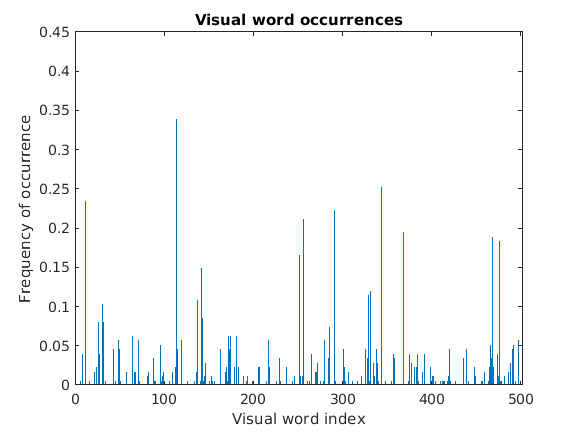


img = readimage(imds, 1);
featureVector = encode(bag, img);

% Plot the histogram of visual word occurrences
figure
bar(featureVector)
title('Visual word occurrences')
xlabel('Visual word index')
ylabel('Frequency of occurrence')


categoryClassifier = trainImageCategoryClassifier(trainingSet, bag);

Training an image category classifier for 2 categories.
--------------------------------------------------------
* Category 1: leopards
* Category 2: llama

* Encoding features for 94 images...done.

* Finished training the category classifier. Use evaluate to test the classifier on a test set.




%confMatrix = evaluate(categoryClassifier, trainingSet);

Evaluating image category classifier for 2 categories.
-------------------------------------------------------

* Category 1: leopards
* Category 2: llama

* Evaluating 94 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                  PREDICTED
KNOWN       | leopards   llama   
---------------------------------
leopards    | 1.00       0.00    
llama       | 0.00       1.00    

* Average Accuracy is 1.00.




confMatrix = evaluate(categoryClassifier, testingSet);

Evaluating image category classifier for 2 categories.
-------------------------------------------------------

* Category 1: leopards
* Category 2: llama

* Evaluating 62 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                  PREDICTED
KNOWN       | leopards   llama   
---------------------------------
leopards    | 1.00       0.00    
llama       | 0.00       1.00    

* Average Accuracy is 1.00.




% Compute average accuracy
mean(diag(confMatrix))

ans = 1